Ist die Nutzung von einzelnen Bandpassfiltern vor jeder Lichtbox zur Umsetzung sinnvoll?

Die Grundidee funktioniert und ist nicht schlecht, da das Signal nahezu in Echtzeit gefiltert und auf den Boxen ausgegeben wird. Problematisch ist die Komplexität und somit auch die Kosten der einzelnen Filter. Je besser ein Filter eine Frequenz herausfiltern soll, desto komplexer muss er werden. (höherer Grad des Filters)

Ist die Nutzung von einzelnen Zeitabschnitten des Signals zur Umsetzung sinnvoll?

Diese Idee ist auch sinnvoll und funktional. Hier büßen wir aber natürlich die Zeit ein, die benötigt wird das Signal aufzuzeichnen (in diesem Fall 0,1s). Diese Verzögerung sollte jedoch kaum merklich sein. Im Gegensatz zum vorherigen Ansatz werden hierfür wesentlich weniger Resourcen benötigt. Letztendlich ist diese Methode also unkomplexer und günstiger.

Grundlegende Überlegungen:

- DFT umschreiben

- 36 Frequenzen gesucht

- beginnt bei Taste d 30 = 146,83 Hz

- endet bei Taste 65 = 1108,73 Hz

- 0,1 Sekunden Refresh-Rate

- Amplitude aus Farbe mappen

- Farben von Blau bis Rot

- Blau, wenn Frequenz keine Amplitude hat / Ruhezustand

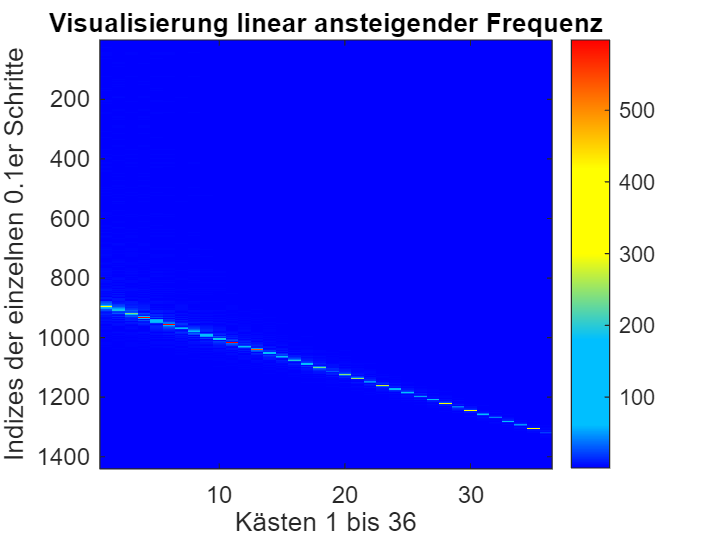

numberOfKeys = 36;
refreshRate = 0.1;
key_min = 30;
key_max = 30 + 36 - 1;

% Frequenzverlauf
[y, Fs] = audioread("frequenztest.wav");
x = (1:length(y))/Fs;

n = Fs * 0.1;
l = floor(length(y) / n);
result = zeros(36, l);
for i = 0:l
    y_part = y((n * i) + 1: n * (i + 1));
    Y = newDFT(y_part, key_min, key_max);
    result(1:36, i+1) = abs(Y);
end

% Höchste Amplitude (niedrigster Wert = 0)
maxAmp = max(max(result));

% Farben als RGB-Vektor
blue = [0, 0, 1];
lightBlue = [0, 0.75, 1];
yellow = [1, 1, 0];
red = [1, 0, 0];

% Erstellung des Farbverlaufs
customColormap = [blue; lightBlue; lightBlue; yellow; yellow; red];
% prozentuale Zuweisung des Farbverlaufs abhängig von Wertebereich
% [0:maxAmp]
customColormap = interp1([0, 0.1, 0.3, 0.5, 0.7, 1], customColormap, linspace(0, 1, maxAmp * 0.8)); % grobe Anpassung des maximalen Ausschlags, da dieser nicht immer auftritt

% Darstellung (Transponieren für die gewünschte Ansicht)
image(transpose(result));
colorbar;
colormap(customColormap);
xlabel("Kästen 1 bis 36");
% für die Zeit müssen die Indizes * 0.1 gerechnet werden
ylabel("Indizes der einzelnen 0.1er Schritte");
title("Visualisierung linear ansteigender Frequenz");



% basslastiges Lied
[y, Fs] = audioread("abstract-future-bass-162604.mp3");
x = (1:length(y))/Fs;

n = Fs * 0.1;
l = floor(length(y) / n);
result = zeros(36, l);
for i = 0:l
    y_part = y((n * i) + 1: n * (i + 1));
    Y = newDFT(y_part, key_min, key_max);
    result(1:36, i+1) = abs(Y);
end

% Höchste Amplitude (niedrigster Wert = 0)
maxAmp = max(max(result));

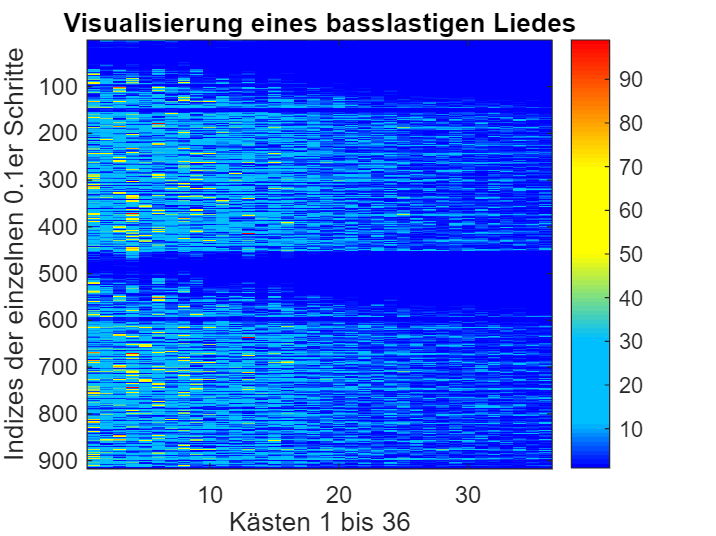


% Erstellung des Farbverlaufs
customColormap = [blue; lightBlue; lightBlue; yellow; yellow; red];
% prozentuale Zuweisung des Farbverlaufs abhängig von Wertebereich
% [0:maxAmp]
customColormap = interp1([0, 0.1, 0.3, 0.5, 0.7, 1], customColormap, linspace(0, 1, maxAmp * 0.8)); % grobe Anpassung des maximalen Ausschlags, da dieser nicht immer auftritt

% Darstellung (Transponieren für die gewünschte Ansicht)
image(transpose(result));
colorbar;
colormap(customColormap);
xlabel("Kästen 1 bis 36");
% für die Zeit müssen die Indizes * 0.1 gerechnet werden
ylabel("Indizes der einzelnen 0.1er Schritte");
title("Visualisierung eines basslastigen Liedes");